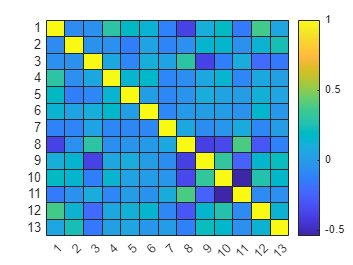

% Step 1: Import the Dataset
data = readtable('C:\\Users\\salem\\Downloads\\dataAI.csv');
data = rmmissing(data);

% Normalize numeric columns to have values between 0 and 1
for i = 1:width(data)
    if isnumeric(data{:, i})
        data{:, i} = (data{:, i} - min(data{:, i})) / (max(data{:, i}) - min(data{:, i}));
    end
end

% Normalize the 'age' column specifically
data.age = (data.age - min(data.age)) / (max(data.age) - min(data.age));

% Initialize a logical array to mark rows with outliers
outliers = false(height(data), 1);

% Define the Z-score threshold for identifying outliers
zThreshold = 3;

% Detect and mark outliers across all numeric columns
for i = 1:width(data)
    if isnumeric(data{:, i})
        zScores = (data{:, i} - mean(data{:, i})) ./ std(data{:, i});
        outliers = outliers | (abs(zScores) > zThreshold);
    end
end

% Remove rows identified as having outliers
data(outliers, :) = [];

% Optionally, save the cleaned and processed data to a new file
writetable(data, 'C:\\Users\\salem\\Downloads\\cleaned_data.csv');

% Step 2: Read Cleaned Data and Rename Columns
data = readtable('C:\\Users\\salem\\Downloads\\cleaned_data.csv');

% Rename columns for better readability
data.Properties.VariableNames{'cp'} = 'ChestPainType';
data.Properties.VariableNames{'trestbps'} = 'RestingBloodPressure';
data.Properties.VariableNames{'chol'} = 'SerumCholestoral';
data.Properties.VariableNames{'fbs'} = 'FastingBloodSugar';
data.Properties.VariableNames{'restecg'} = 'RestingECG';
data.Properties.VariableNames{'thalach'} = 'MaxHeartRate';
data.Properties.VariableNames{'exang'} = 'ExerciseInducedAngina';
data.Properties.VariableNames{'oldpeak'} = 'STDepression';
data.Properties.VariableNames{'slope'} = 'SlopeSTSegment';
data.Properties.VariableNames{'ca'} = 'NumMajorVessels';
data.Properties.VariableNames{'thal'} = 'Thal';

% Step 3: Exploratory Data Analysis (EDA)
sum(ismissing(data));
correlationMatrix = corr(table2array(data(:, 1:end-1)));
figure;
heatmap(correlationMatrix, 'Colormap', parula, 'ColorbarVisible', 'on');


% Step 4: Calculating Age Statistics
minAge = min(data.age);
maxAge = max(data.age);
meanAge = mean(data.age);
fprintf('Min Age: %.2f, Max Age: %.2f, Mean Age: %.2f\n', minAge, maxAge, meanAge);

Min Age: 0.00, Max Age: 1.00, Mean Age: 0.53


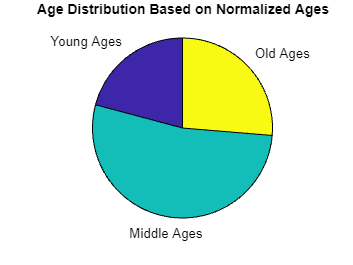


% Step 5: Age Distribution Pie Chart
% Redefine age groups for normalized data
young = data.age < 1/3;
middle = data.age >= 1/3 & data.age < 2/3;
old = data.age >= 2/3;

% Plot pie chart with normalized age groups
ageGroups = [sum(young), sum(middle), sum(old)];
labels = {'Young Ages', 'Middle Ages', 'Old Ages'};
figure;
pie(ageGroups, labels);
title('Age Distribution Based on Normalized Ages');